Código beta de esta función.

function datos = FUNCION_PFG_MEJORADA_v34(datos, datos2, par_rueda, litros_fuel)

Se elimina la primera fila de NaNs de la simulación:

datos2 = datos2(2:height(datos2),:);

Se toman los tiempos en común entre el dataframe real y la simulación:

tiempo = datos.tiempo;
tiempo2 = datos2.Time;
datos = datos(ismember(tiempo,tiempo2),:);
datos2 = datos2(ismember(tiempo,tiempo2),:);

Cojo la densidad del aire:

dair = datos2.AirDensity(1);

Se introducen los datos:

La masa del coche $m_a$ es de 796 kg.

ma = 796;

La masa del piloto $m_p$ es de 80 kg.

mp = 80;

La masa del combustible $m_F$ es el número de litros $l$ por la densidad $\sigma$.

d = 0.76;
mf = litros_fuel*d;

El $A_F$ es de 1,835 $m^2$.

af = 1.835;

La proporción del peso sobre el eje delantero (respecto al peso total) es de 0,454 (obtenido del reglamento de la FIA).

peso_delante = 0.454;

La proporción del peso sobre el eje trasero (respecto al peso total) es de 0,546.

peso_trasero = 0.546;

Se toma la posición del eje delantero como x=0, y el suelo en su posición, como z=0:

pos_eje_del = 0;

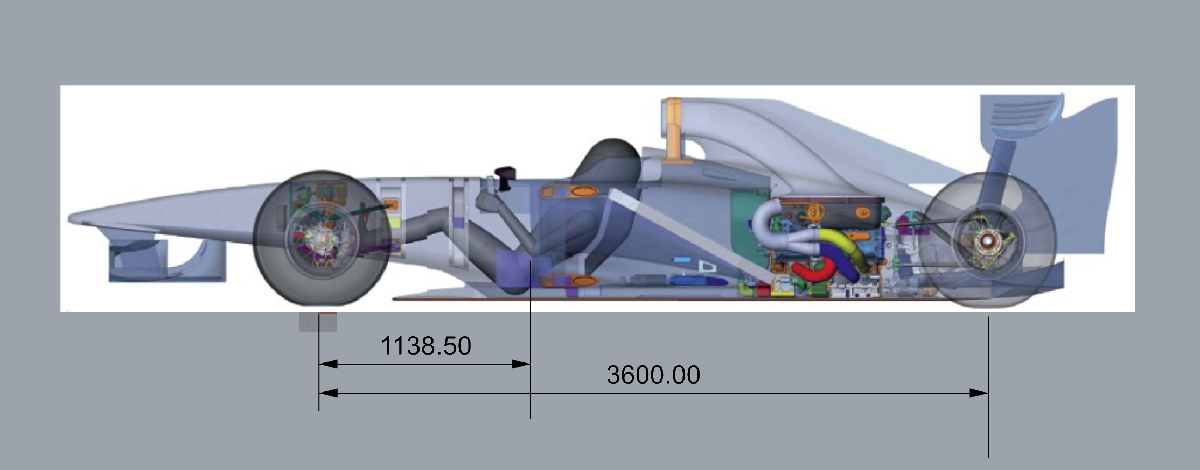

Se estima que la posición del piloto es de 1,139 m en el eje x, a la altura de la cadera, a partir de la anterior figura:

pos_piloto = 1.139;

Se estima que la posición de la batalla es de 3,6 m en el eje x, a partir de la anterior figura:

batalla = 3.6;

Se toma la posición del eje trasero: el eje delantero más la batalla.

pos_eje_tras = pos_eje_del+batalla;

Se toma la posición del coche en el centro:

pos_coche_centro_x = (0.454*(ma+mf+mp)*pos_eje_del+0.546*(ma+mf+mp)*pos_eje_tras)/(ma+mf+mp);

La altura del eje trasero en z $z_R$ es de 0,33 (la mitad del diámetro de la rueda en el eje z), ya que la rueda tiene 660 mm de altura (dato obtenido del MSI).

zr = 0.33;

Se guarda la carga delantera del coche (obtenidos de datos de simulación):

carga_frontal = (datos2.TireLoadFL + datos2.TireLoadFR)/2;

Se guarda la carga trasera del coche (obtenidos de datos de simulación):

carga_trasera = (datos2.TireLoadRL + datos2.TireLoadRR)/2;

Consultada la altura del centro de masas del coche con piloto en el MSI es de 190 mm, esto es, 0'19 m.

centro_z = 0.19;

Se calcula la distancia del centro de masas al piloto, al eje delantero y al eje trasero:

dgpiloto = abs(pos_coche_centro_x-pos_piloto);
dgejedel = abs(pos_coche_centro_x-pos_eje_del);
dgejetras = abs(pos_coche_centro_x-pos_eje_tras);

Se crea el vector solución:

solucion = zeros(height(datos),4);

Se crea la matriz para cada conjunto de datos.

Se aplica la segunda ley de Newton al monoplaza con las fuerzas longitudinales:


$$\sum \vec{F} =m_T \cdot \vec{a} \to \sum \vec{F_{\textrm{LONG}} } =m_T \cdot \vec{a_{\textrm{LONG}} }$$


Que en este caso, las fuerzas longitudinales serán el empuje $T$, la resistencia aerodinámica (también llamado drag) $D$ y las fuerzas de rozamiento delantera y trasera $F_{\textrm{ROZDEL}}$ y $F_{\textrm{ROZTRAS}}$:

NOTA: El empuje es el momento del motor partido por el radio: $\frac{M_{\textrm{MOTOR}} }{R}$:


$$\frac{M_{\textrm{MOTOR}} }{R}-D-F_{\textrm{ROZDEL}} -F_{\textrm{ROZTRAS}} =m_T \cdot a_{\textrm{LONG}}$$


Donde:

1)$D=0\ldotp 5\cdot \zeta_{\textrm{AIRE}} \cdot A_F \cdot V^2 \cdot C_D$

2)$F_{\textrm{ROZDEL}} =\alpha_{\textrm{DEL}} \cdot N_{\textrm{DEL}}$, donde $N=m_T \cdot g\cdot b_{\textrm{DEL}} +L_F$

3)$F_{\textrm{ROZTRAS}} =\alpha_{\textrm{TRAS}} \cdot N_{\textrm{TRAS}}$, donde $N=m_T \cdot g\cdot b_{\textrm{TRAS}} +L_R$

Por lo que la ecuación queda de la siguiente forma:


$$\frac{M_{\textrm{MOTOR}} }{R}-0\ldotp 5\cdot \zeta_{\textrm{AIRE}} \cdot A_F \cdot V^2 \cdot C_D -\alpha_{\textrm{DEL}} \cdot N_{\textrm{DEL}} -\alpha_{\textrm{TRAS}} \cdot N_{\textrm{TRAS}} =m_T \cdot a_{\textrm{LONG}}$$


Por otro lado, las fuerzas se aplican al coche desde el centro de masas, sin embargo, hay fuerzas (como el empuje del motor) que se aplican en otros lugares del monoplaza.


$$\sum M_{y_G } =0=W_p \cdot d_{\textrm{GTGP}} +T\cdot Z_{\textrm{GTejeR}} +\left(L_F +W_L \right)\cdot d_{\textrm{GTejeF}} -\left(L_R +W_R \right)\cdot d_{\textrm{GTejeR}} -N_F \cdot \left(d_{\textrm{GTejeF}} \right)+N_R \cdot \left(d_{\textrm{GTejeR}} \right)+F_{\textrm{ROZDEL}} \cdot Z_G +F_{\textrm{ROZTRAS}} \cdot Z_G$$


Donde la normal frontal y la normal trasera es:


$$L_F +L_R +m_T \cdot g-N_F -N_R =0$$


El sistema que queda es el siguiente:


$$\begin{array}{l}
m_T \cdot a_{\textrm{LONG}} \left(i\right)=\frac{M_{\textrm{MOTOR}} }{R}-0\ldotp 5\cdot \zeta_{\textrm{AIRE}} \left(i\right)\cdot A_F \cdot {V\left(i\right)}^2 \cdot C_D -\alpha_{\textrm{DEL}} \cdot N_{\textrm{DEL}} -\alpha_{\textrm{TRAS}} \cdot N_{\textrm{TRAS}} \\
\sum M_{y_G } =0=W_p \cdot d_{\textrm{GTGP}} +M_{\textrm{MOTOR}} +\left(L_F \left(i\right)+W_L \right)\cdot d_{\textrm{GTejeF}} -\left(L_R \left(i\right)+W_R \right)\cdot d_{\textrm{GTejeR}} -N_{\textrm{DEL}} \left(i\right)\cdot \left(d_{\textrm{GTejeF}} \right)+N_{\textrm{TRAS}} \left(i\right)\cdot \left(d_{\textrm{GTejeR}} \right)\;\;+F_{\textrm{ROZDEL}} \left(i\right)\cdot Z_G +F_{\textrm{ROZTRAS}} \left(i\right)\cdot Z_G 
\end{array}$$


normal_delantera = (ma+mp+mf)*9.8*peso_delante+carga_frontal;
normal_trasera = (ma+mp+mf)*9.8*peso_trasero+carga_trasera;
normal = zeros(height(datos),1);
for i=1:height(datos)
    matriz = zeros(2,2);
    b = zeros(2,1);
    normal(i) = carga_frontal(i)+(ma+mp+mf)*9.8*peso_delante+(ma+mp+mf)*9.8*peso_trasero+carga_trasera(i);
    matriz(1,1) = -0.5*af*datos2.AirDensity(i)*datos.Speed_m_s(i)^2;
    matriz(1,2) =  -normal(i);
    matriz(2,2) =  normal(i);
    b(1) = (ma+mp+mf)*datos.aceleracion_m_s_2(i)-par_rueda(i)/zr;
    b(2) = -(-dgpiloto*mp*9.8-((ma+mp+mf)*peso_delante+carga_frontal(i))*dgejedel+((ma+mp+mf)*peso_trasero+carga_trasera(i))*dgejetras+normal_delantera(i)*dgejedel-normal_trasera(i)*dgejetras);
    vsol = matriz^-1*b;
    solucion(i,1) = vsol(1);
    solucion(i,2) = vsol(2);
end

Se toma el empuje, el drag y la potencia calculada y se incluye en el dataframe:

datos.cd2 = solucion(:,1);
datos.drag2 = solucion(:,1)*dair.*datos.Speed_m_s.^2*af*0.5;
datos.frozdel2 = solucion(:,2).*normal_delantera;
datos.froztras2 = solucion(:,2).*normal_trasera;
datos.errorcd = abs(datos.cd-datos.cd2);
datos.carga_estimada = (carga_frontal + carga_trasera)/2;
datos.normal = (normal_delantera + normal_trasera)/2;
datos.froz = (datos.frozdel2 + datos.froztras2)/2;
datos.nu = mean(datos.froz./datos.normal)*ones(height(datos),1);
datos.carga_real = datos.froz./datos.nu-datos.normal;
datos.normal = datos.froz./datos.nu+datos.carga_real;
datos.nu = mean(datos.froz./datos.normal)*ones(height(datos),1);
datos.carga_real = datos.froz./datos.nu-datos.normal;
end